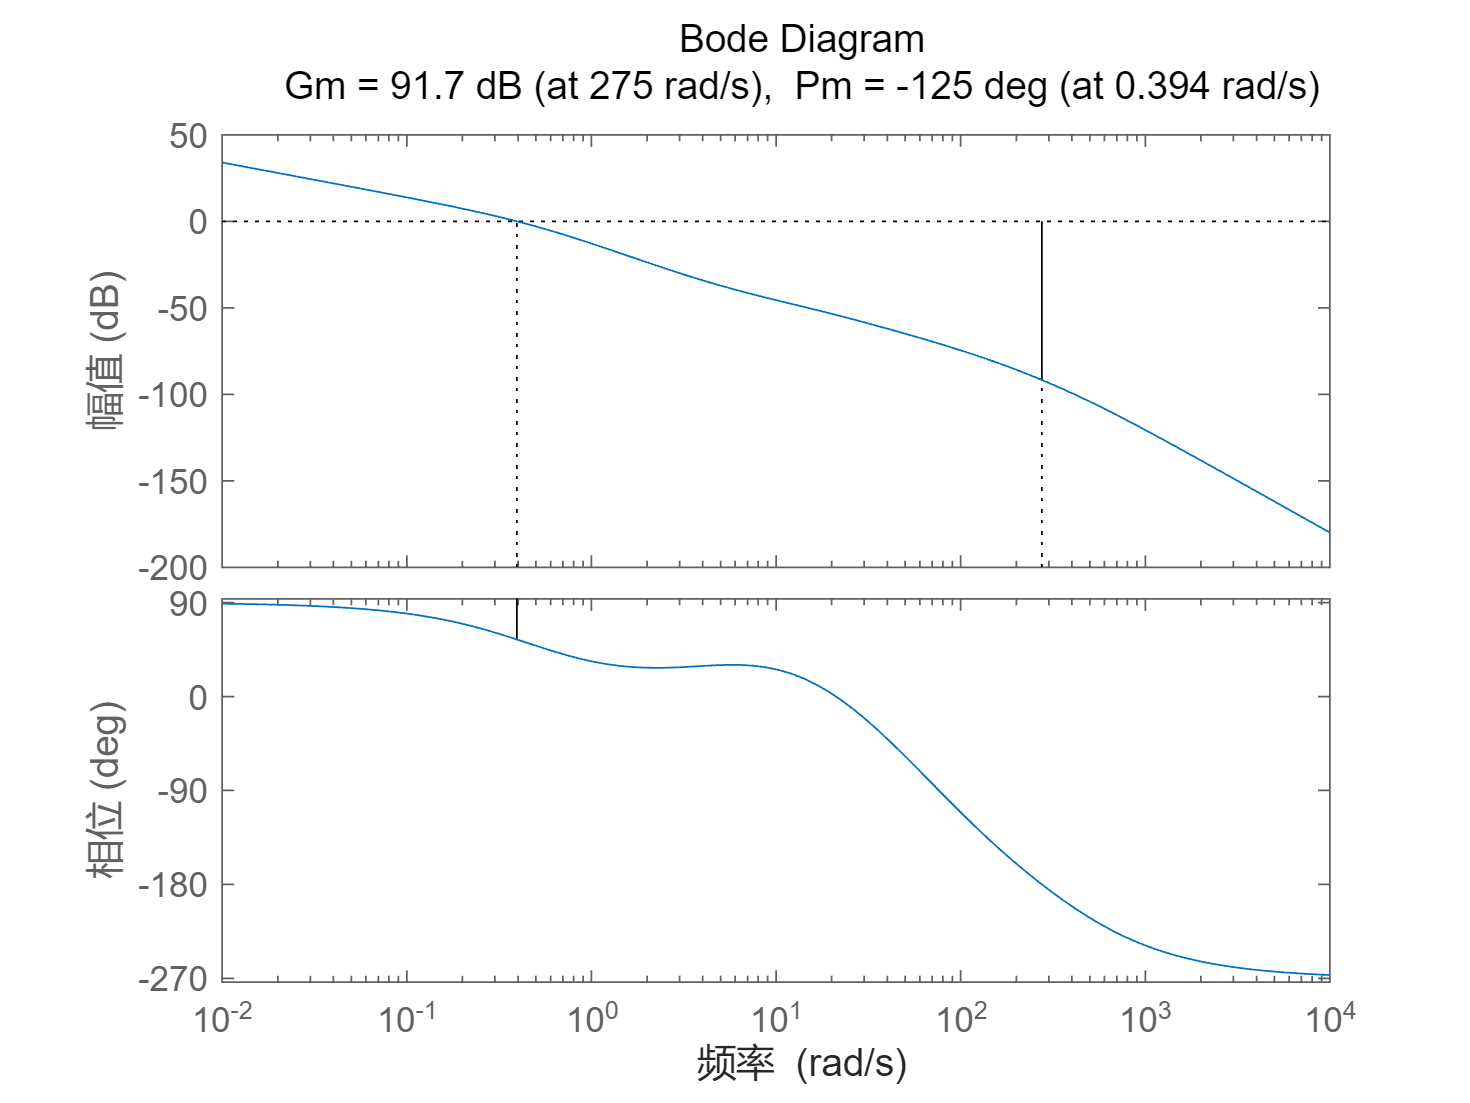

clc;
close all;
clear all;

s  = tf('s');
Gp = 1000*(s+5)*(s-50)/(s*(s+0.5)*(s+25)*(s+100)*(s+400));
w = logspace(-1,1.2,100);
margin(Gp); 

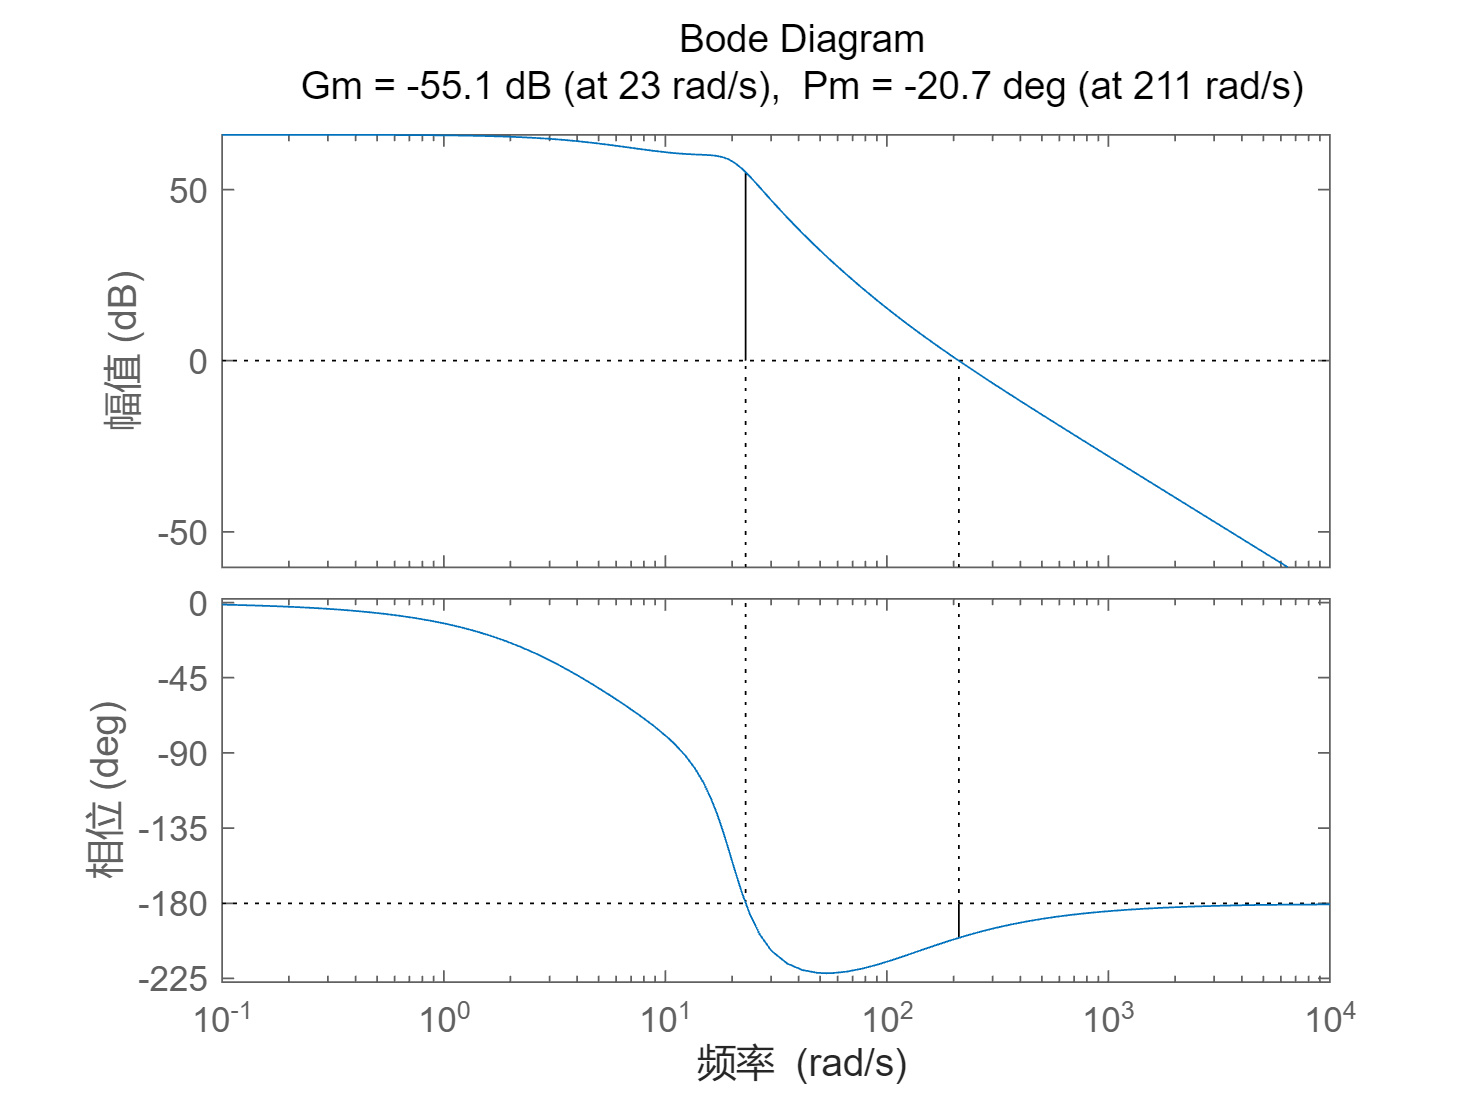

s  = tf('s');
Gp2 = 100*20*20*(s+100)/((s+5)*(s^2+2*0.3*20*s+20^2));
margin(Gp2); 

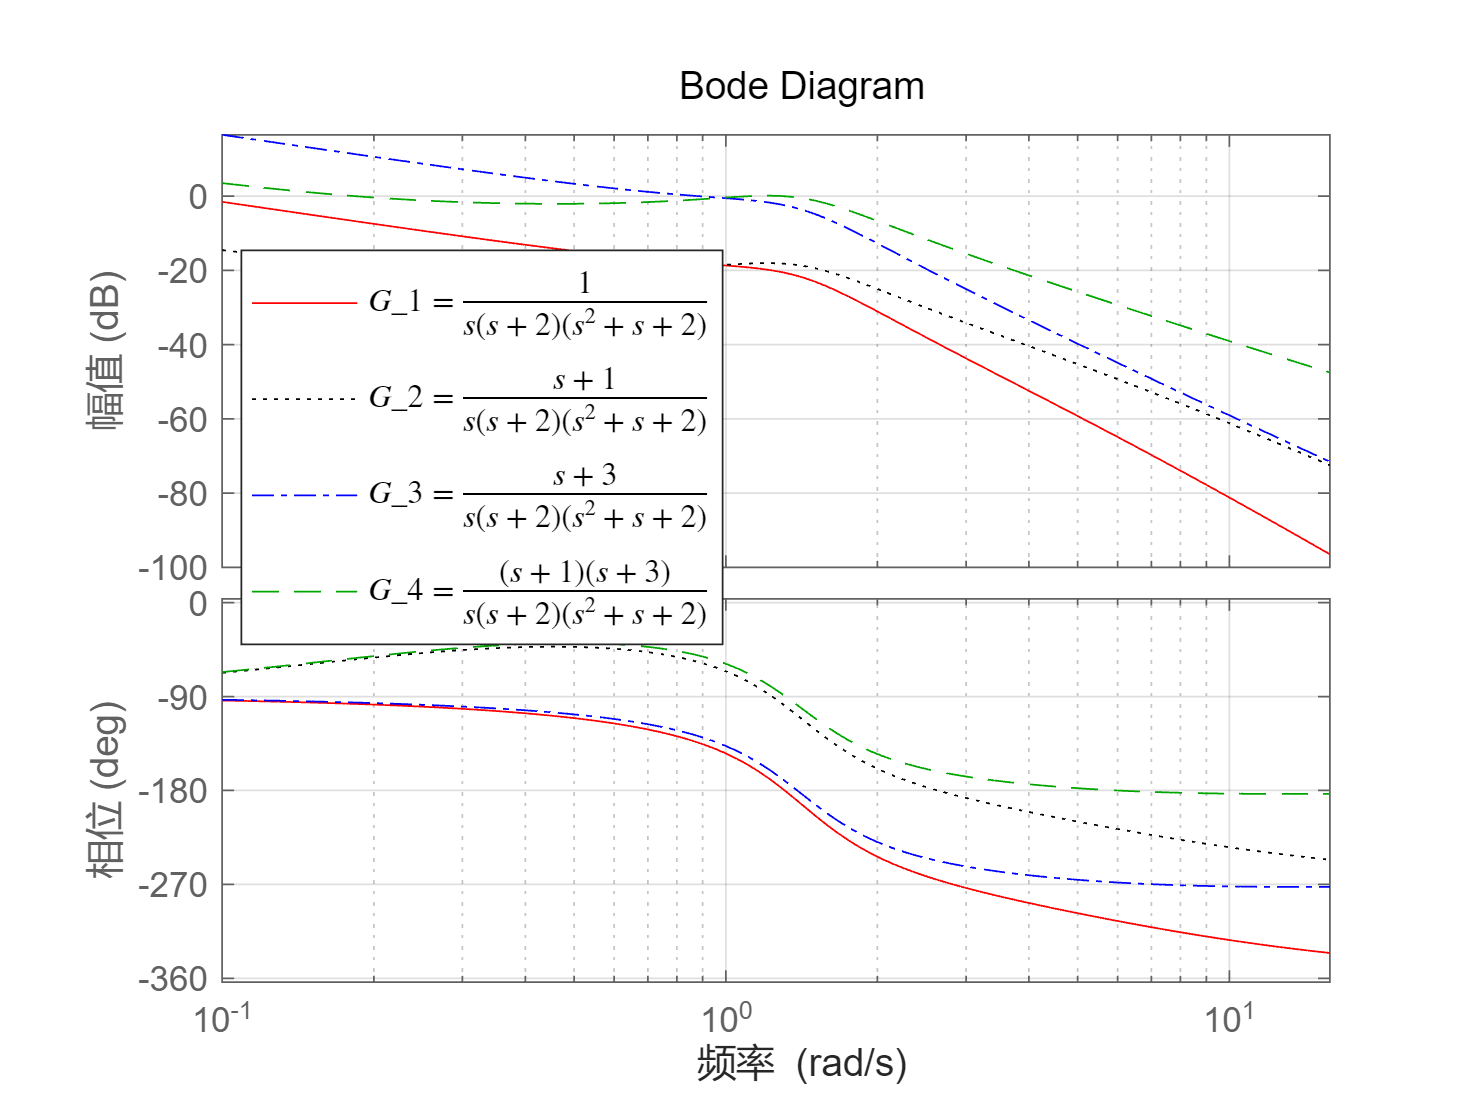


s = tf('s');

G1 = 1/(s*(s+6)*(s^2+s+2));
G2 = (s+0.2)/(s*(s+6)*(s^2+s+2));
G3 = (s+8)/(s*(s+6)*(s^2+s+2));
G4 = ((s+0.2)*(s+8))/(s*(s+6)*(s^2+s+2));
w = logspace(-1,1.2,100);

bode(G1,'r-',G2,'black:', G3,'b-.',G4,'g--',w);

grid on; 

hh = legend('$G_1=\frac{1}{s(s+2)(s^2+s+2)}$','$G_2=\frac{s+1}{s(s+2)(s^2+s+2)}$','$G_3 =\frac{s+3}{s(s+2)(s^2+s+2)}$','$G_4=\frac{(s+1)(s+3)}{s(s+2)(s^2+s+2)}$',"Position", [0.16476,0.41645,0.32679,0.35595]);
%hh = legend('$G_1$','$G_2$','$G_3$','$G_4$');
set(hh,'Interpreter','latex'); 

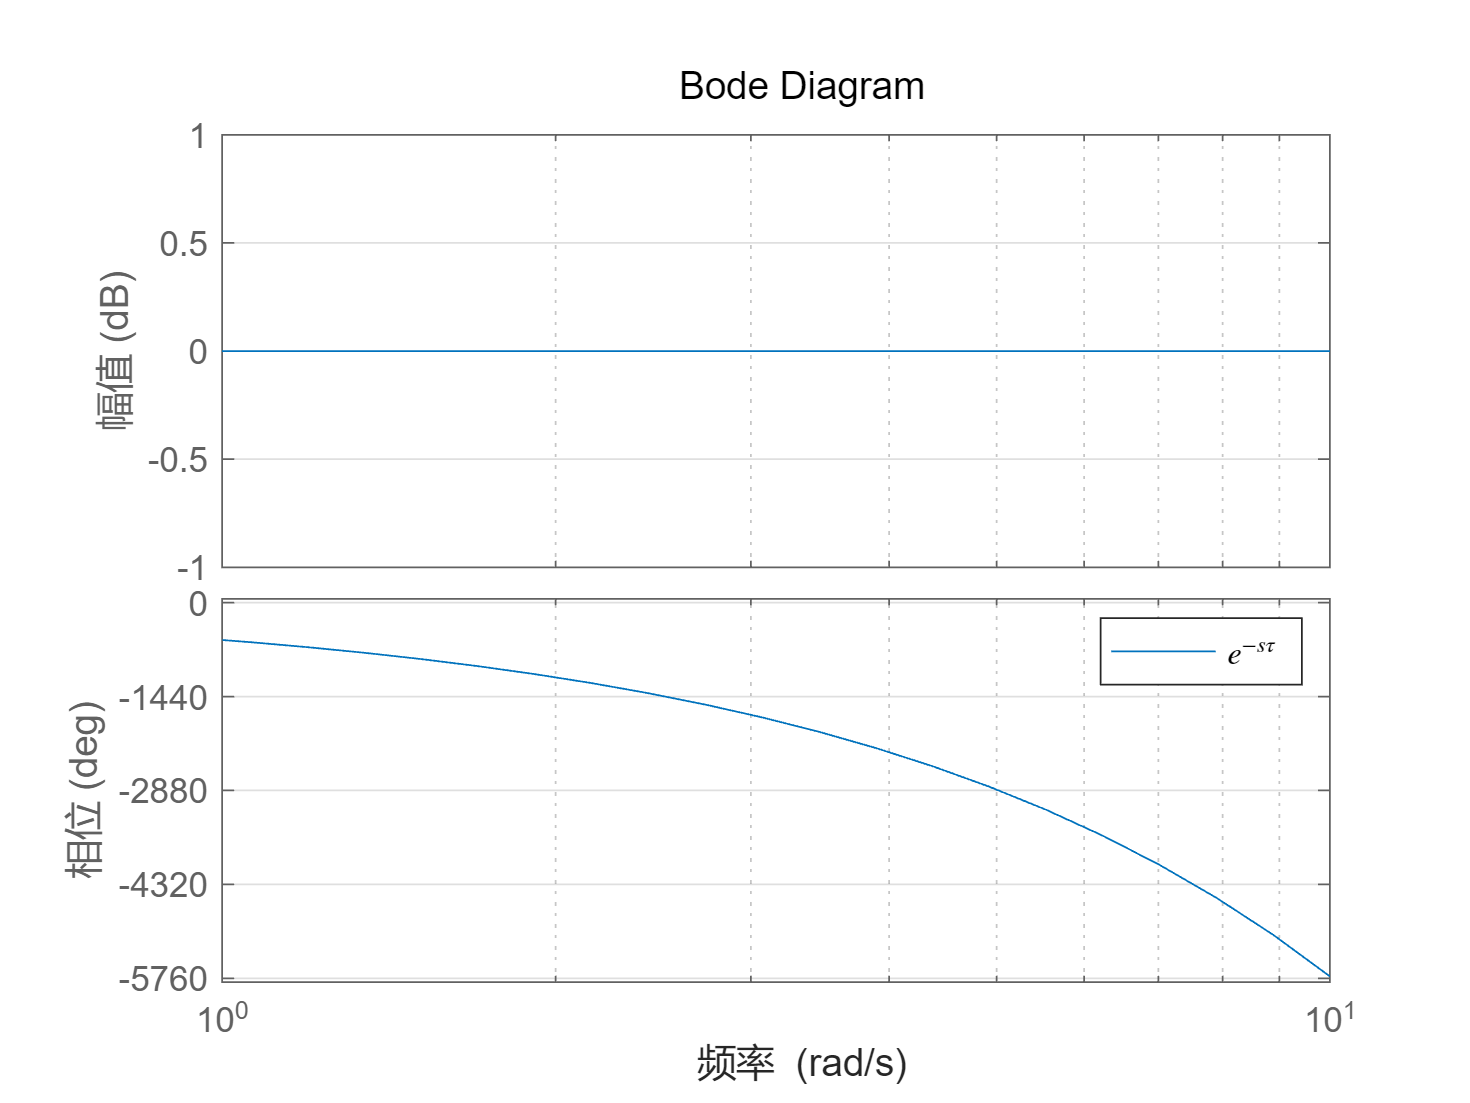

s = tf('s');

Gd = exp(-s*10);
bode(Gd);
grid on; 

w = logspace(-2,2,100);

hh = legend('$e^{-s\tau}$');
 
set(hh,'Interpreter','latex'); 

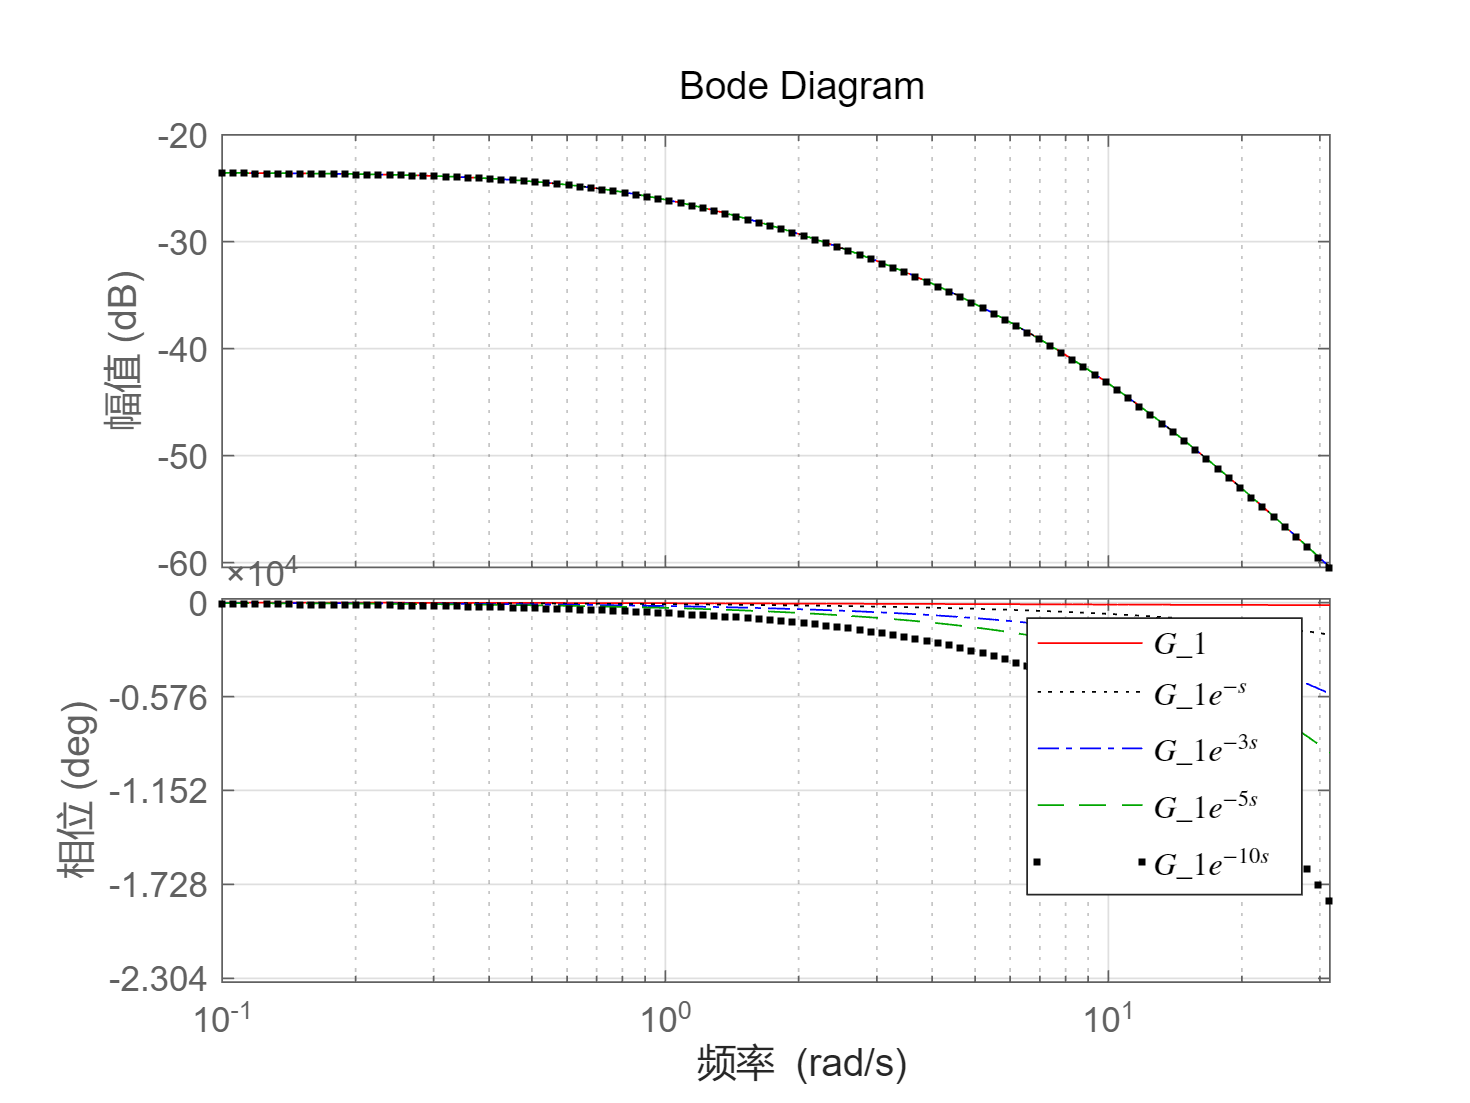

s = tf('s');

G1 =  (s+2)/((s+1)*(s+3)*(s+10));
G2 =  exp(-s*1)*G1;
G3 =  exp(-s*3)*G1;
G4 =  exp(-s*5)*G1;
G5 =  exp(-s*10)*G1;

w = logspace(-1,1.5,100);

bode(G1,'r-',G2,'black:', G3,'b-.',G4,'g--',G5,'black.',w);

grid on; 

hh = legend('$G_1$','$G_1 e^{-s }$','$G_1 e^{-3s }$','$G_1 e^{-5s }$','$G_1 e^{-10s }$');
set(hh,'Interpreter','latex'); 